# Modeling total cases based on time

There are different approaches depending on what variables we are using to make the prediction. Basic fitting, curve fitting, econometrics models, and even machine and deep learning

## Polynomial Fitting

Begin with a simple polynomial fit.

load usData

Use a numeric value for x (time since Jan 1, 2020).

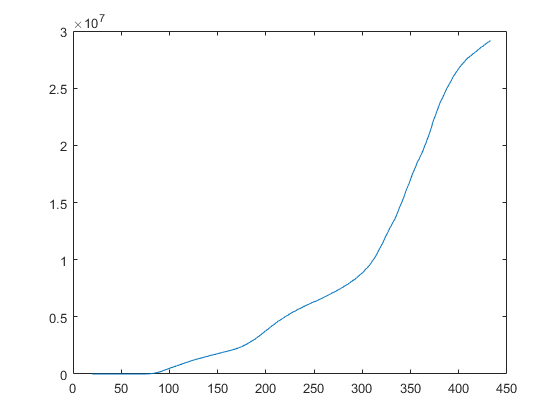

us.dayval = us.date - datetime(2020,1,1);
us.dayval = days(us.dayval);
plot(us.dayval,us.cases)

Use basic fitting tool dropdown from the plot. 

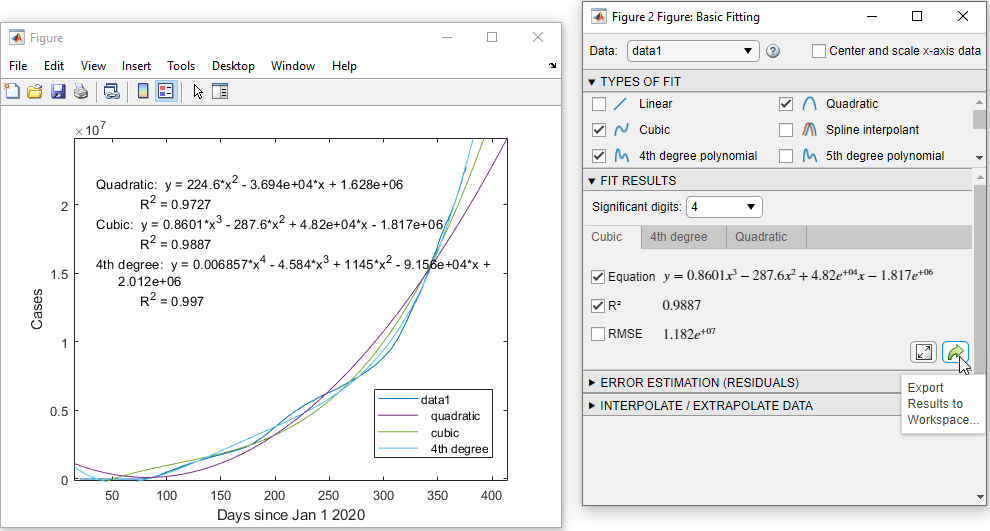

Explore types of fits based on polynomial order. Choose the best and export to the workspace (try cubic in this case)

You can generate code from the visualization which includes the code to predict! The app uses `polyfit`, so we want to use `polyval` for predictions. 

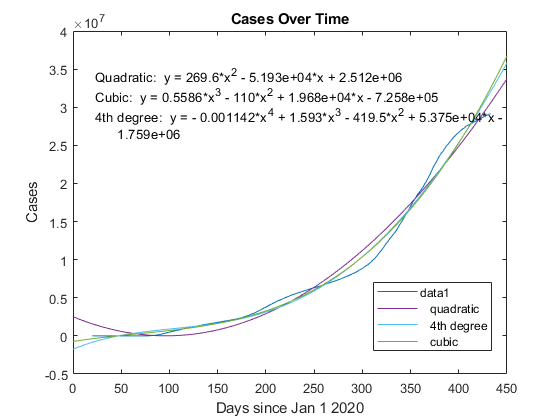

createfigure(us.dayval,us.cases)

Explore the cubic fit output.

load cubicFit.mat
fit

fit = struct with fields:
     type: 'polynomial degree 3'
    coeff: [0.8601 -287.5501 4.8198e+04 -1.8166e+06]

Predict for next 30 days with the cubic fit.

m = max(us.dayval);
tforecast = (m:m+30)';
t = [us.dayval;tforecast];
y = polyval(fit.coeff,t);

Visualize

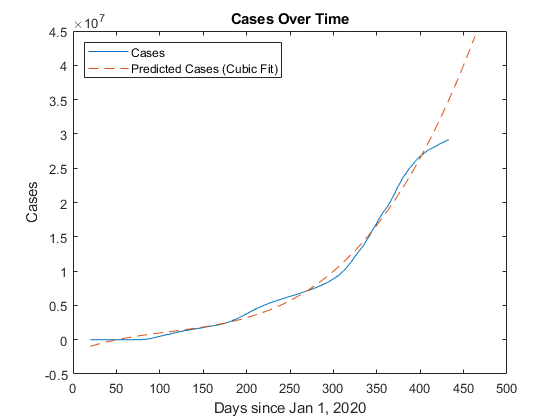

plot(us.dayval,us.cases)
hold on
plot(t,y,'--')
hold off
ylabel("Cases")
xlabel("Days since Jan 1, 2020")
title("Cases Over Time")
legend("Cases","Predicted Cases (Cubic Fit)","Location","northwest")

Of course, we want to be wary of using this as a definite prediction. There is much to take into account, but it is very useful in exploration.

Let's use more sophisticated time series modeling such as ARIMA or GARCH. 

## Time-series econometrics models

Use the Econometrics Modeler app for time series modeling. You can experiment, discover the best fits based on visualizations and hypothesis testing, export the model and generate the code to create the models. You can also get a report to summarize the session.

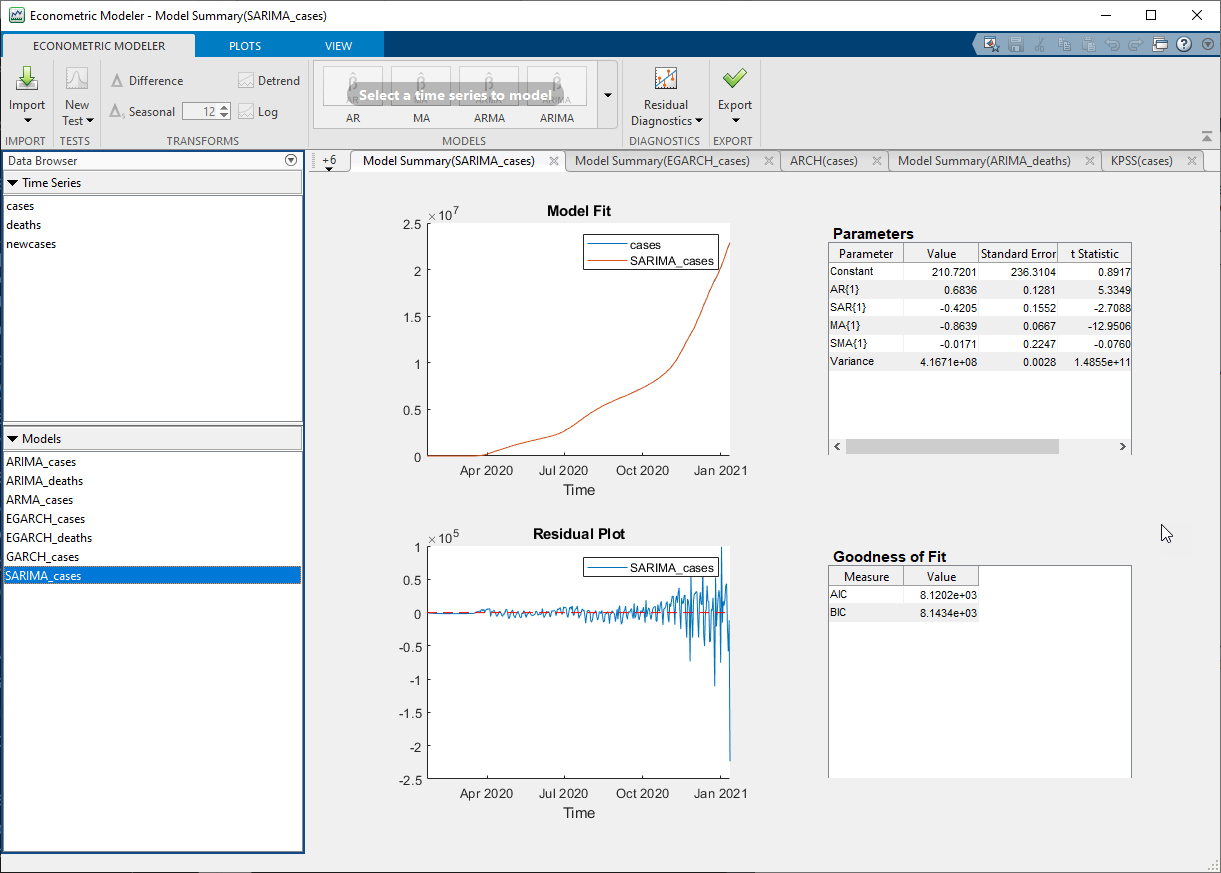

Examine the generated function [./Models\modelTimeSeries.mlx](matlab:open('./Models\modelTimeSeries.mlx')) 

Load the previously saved models.

load ARIMAmodel.mat

Explore the model info.

summarize(ARIMA_cases)

 
   ARIMA(1,1,1) Model (Gaussian Distribution)
 
    Effective Sample Size: 358
    Number of Estimated Parameters: 4
    LogLikelihood: -4057.94
    AIC: 8123.88
    BIC: 8139.4
 
                  Value       StandardError    TStatistic      PValue  
                __________    _____________    __________    __________
    Constant        661.47         2004.1         0.33006       0.74136
    AR{1}          0.99336      0.0097229          102.17             0
    MA{1}          -0.5656        0.02905          -19.47    1.9872e-84
    Variance    4.2644e+08        0.16891      2.5246e+09             0
 
 


Lets check the quality of the model. Use the simulate function to predict the sequential data points based on the model 

rng(5432)
n = 400;
y = simulate(ARIMA_cases,n);
figure
plot(us.cases)
ylabel("Cases")
title("Cases Over Time")
hold on
plot(y,"--")

Keep simulating and adding more.

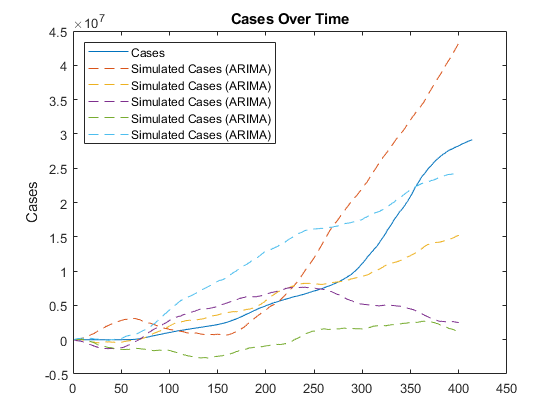

plot(simulate(ARIMA_cases,n),"--")  
plot(simulate(ARIMA_cases,n),"--")
plot(simulate(ARIMA_cases,n),"--")
plot(simulate(ARIMA_cases,n),"--")
hold off
legend(["Cases",repmat("Simulated Cases (ARIMA)",1,5)],"Location","northwest")

We could continue (simulate many many) and use this to try to understand the data.

If we just wanted to forecast or predict, we can pass the value of number of days to `forecast`.

n = 30;
y = forecast(ARIMA_cases,n,us.cases);

Visualize the predictions.

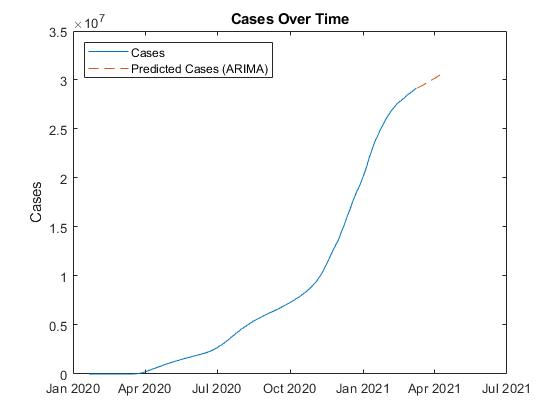

fdates = us.date(end) + caldays(1:n);
figure
plot(us.date,us.cases)
hold on
plot(fdates,y,"--")
hold off
ylabel("Cases")
title("Cases Over Time")
legend("Cases","Predicted Cases (ARIMA)","Location","northwest")

These models don't take into account some of the inflections and other variables. There is much more we can do within the app to improve the model, check equations with research, and more.

## Deep learning

We can also explore using deep learning for time series modeling.

Use the example for chicken pox in the [documentation](https://mathworks.com/help/deeplearning/ug/time-series-forecasting-using-deep-learning.html) and explore using the Covid-19 case data from our example.

edit CovidTimeSeriesForecastingUsingDeepLearningExample.mlx